# Machine Learning (ML) Theory

## What happens under the hood when we build a model?

- Understanding how ML algorithms work can help choose the appropriate model and parameters, and help interpret errors and model failure.

- Some models are transparent (e.g. regression) - we can see the underlying equations.

- Most ML algorithms are a "black box"

- Nevertheless, all ML can be considered a type of optimization.

- ML algorithms *optimize* for increased accuracy or reduced error.

## Cost function and optimization objective

- Optimzation refers to minimizing or maximizing a function *f(x) _by altering _x*. (*f(x)* is called the objective function or cost function)

- For example, if *x* is the value of blood glucose above which a patient is diabetic, and *f(x)* is the accuracy of identifying diabetic patients, then the goal of ML algorithm is to change *x _so that is optimizes _f(x)*.

## Finding the right cost function

- In some cases, the cost function is straightforward - e.g. reducing the error in classification of patients (diabetes vs normal).

- Sometimes it is difficult to decide what should be optimized. For example, should we measure the accuracy of binary classification (normal vs disease) or extent of the disease (stages of heart disease). Should we give partial credit for getting close to the right stage?

- Should we penalize small but frequent errors, or large but rare errors?

## Examples of cost functions

- For regression (most common): **MSE - Mean squared error**

$\mathrm{mean}\left(|Y-\mathrm{Ypred}|^{2\;} \right)\;$ or $\frac{\left({\mathrm{sum}\left(Y-\mathrm{Ypred}\right)}^2  \right)}{\mathrm{length}\left(Y\right)}$

- Regression: **MAE - Mean absolute error**


$$\mathrm{mean}\left(|Y-\mathrm{Ypred}|\right)$$


*MSE gives higher weight to large errors. In contrast, MAE increase linearly with error.

- For classification: **cross-entropy or log loss**


$$\left(y*\mathrm{log}\left(p\right)+\left(1-y\right)*\mathrm{log}\left(1-p\right)\right)$$


where _y _is 0 or 1, and _p _is the predicated probabilty (e.g. from logistic regression)

## How do we optimize the cost function?

- Calculus!

- In general, for building a ML model, we try to minimize an objective.

%% * The minimum of a function can be found using differentiation. * Find_ f'(x) *or _dy/dx* * F(x) is minimum or maximum when *f'(x) = 0* * Points where _f'(x) = 0 _are known as critical points or stationary points. * A local minimum is a point where _f(x) _is lower than all neighboring points

## Finding minima using Gradient descent

- Make a small change to *x* and calculate *f(x)* and *f'(x)*. The value of slope tells you how to change *x*.

- In the gradient descent approach, the algorithm makes small changes in _x _ with the opposite sign of the slope until you hit slope = 0.

- A point that obtains the absolute lowest value of *f(x)* is a global minimum.

- This approach can be scaled to multiple variables using partial derivatives.

## Gradient descent - parameters

- In practice, the algorithm may never hit zero precisely, but a very small number close zero (say 1E-6). We can enforace the number below which we can assume the slope to be zero (e.g. 1E-6). This number is called the **tolerance**.

- An important parameter in Gradient Descent is the **step size** or **learning rate**. If the learning rate is too small, then the algorithm will take a long time to find the minima. If the learning rate is too high, it might miss the minima and jump across the valley.

%% Regression

- Consider a linear regression model to predict Y from X.

- Ypred = mX

- The goal is to find "m" that best "fits" the data - i.e. minimizes the difference between Y and Ypred.

- Cost function - **Mean squared error (MSE)**


$$\mathrm{mean}\left(|Y-\mathrm{Ypred}|^{2\;} \right)\;$$


- the cost function changes as you change "m"

- Optimization goal: find "m" that minimizes MSE

- the best "m" is found by MATLAB using gradient descent

## Regularization

- Framework to reduce overfitting

- Idea: find the simplest model that explains the data.

- Penalize complexity - for example if a linear model with a single parameter does equally well as a quadratic model with two parameters, then the linear model is chosen.

- Hyperparameter (lambda, $\lambda$) - penalizes complexity

## Finding the best regularization model

- The optimization objective: Minimize MSE + Minimize regression coefficients

`min(MSE+lambda*beta)`

- If *lambda = 0,* then it is normal regression

- How to find the best *lambda*?

- Cross validation!

- Do cross validation on the training set.

## Regularization approach: Lasso regression

- *Lasso regression *penalizes model complexity; identifies the simplest model by removing correlated variables.

- Lasso with 3-fold cross-validation to find best lambda:

`[B, FitInfo] = lasso(X,Y,"CV",3);`

- Let's compare Traditional regression vs Lasso regression

## Test models using simulated data

- Simulated datasets are very useful for understanding how models work - since we know the right "answer" (i.e. the model that best explains the data, as we created the model).

- Let's create a simple linear model that's a function of 2 variables + 4 noise variables.

Regression coefficients; only 1st and 2nd are non-zero:

beta = [1;5;0;0;0;0];

Create a random variable X from a normal distribution with mean 0 and variance 1:

X = normrnd(0,1,[50,6]);

Y = f(x) + noise:

y = X*beta + randn(50,1);

Note that the number of columns of the 1st matrix must equal the number of rows of the 2nd matrix.

## Compare Traditional regression vs Lasso in simulated data

[B1, Fit] = lasso(X,y,"CV",3);
B1_lasso = B1(:,Fit.Index1SE)

B1_lasso =     0.8677
    4.7617
   -0.1311
         0
         0
         0


B2 = regress(y,X);

*Fit.IndexMinMSE* has the best lambda that has the lowest mean squared error during CV.

*Fit.Index1SE* has the sparsest model (with least number of predictors) within 1 standard deviation of the lowest error.

- Which B is closer to the actual Betas used to generate Y?

- **Test accuracy of both methods using 3-fold cross validation.**

regf=@(XTRAIN,ytrain,XTEST)(XTEST*regress(ytrain,XTRAIN));

X1 = [ones(size(y,1),1),X];
cvMse = crossval('mse',X1,y,'predfun',regf)

cvMse = 1.0829

indices = crossvalind("kfold", size(X,1), 10);

for i = 1:10
    test = indices == i;
    train = test;
    
    Xtrain = X(train,:);
    ytrain = y(train,:);
    
    %[B1, Fit] = lasso(X,y,"CV",10);
    %B1_lasso = B1(:,Fit.Index1SE);
    
    B2 = regress(ytrain,Xtrain);
    
    Xtest = X(test,:);
    ytest = y(test,:);
    
    ypred = Xtest*B2;
    RMSE = sqrt(mean(ypred-ytest).^2)
end 

RMSE = 2.0206e-15

RMSE = 8.8818e-17

RMSE = 8.8818e-17

RMSE = 5.9952e-16

RMSE = 5.3291e-16

RMSE = 1.8013e-15

RMSE = 4.4409e-16

RMSE = 0

RMSE = 1.1102e-17

RMSE = 8.6042e-17

## Stepwise regression

B3 = stepwisefit(X,y);

Initial columns included: none
Step 1, added column 2, p=7.38281e-28
Step 2, added column 1, p=6.71821e-12
Step 3, added column 3, p=0.0130416
Final columns included:  1 2 3 
    'Coeff'      'Std.Err.'    'Status'    'P'         
    [ 1.0299]    [  0.1048]    'In'        [7.1241e-13]
    [ 4.9078]    [  0.1280]    'In'        [1.4660e-36]
    [-0.3150]    [  0.1220]    'In'        [    0.0130]
    [ 0.0588]    [  0.1465]    'Out'       [    0.6902]
    [ 0.0524]    [  0.1476]    'Out'       [    0.7241]
    [-0.0014]    [  0.1239]    'Out'       [    0.9913]



Adds each predictor in each step rather than everything simultaneously.

- A new predictor is added only if it provides complementary information.

- The algorithm terminates when no further addition can improve the model.

- If two variables are highly correlated, then only one is chosen -> this leads to a simpler model with fewer predictors.

- **Test accuracy of stepwise regression using the simulated data**

## Partial least square (PLS) regression

- This approach first groups predictors into groups/clusters similar to principal component analysis (PCA) or clustering.

- It then performs regression on these clusters thereby reducing the number of features used in the regression model.

- In PLS regression you can specify the number of predictors you want in the final model.

- Example:

[Xl,Yl,Xs,Ys,betasPLS,PctVar] = plsregress(X,y,3);

- Here the number of predictors is 3

- The *PctVar* output provides feature importance - it tells you what percentage of variance is explained by each component (just like PCA)

- _Xl _provides relative weights of each predictor onto each component. For example, if there are 20 features and 5 components, the _Xl _is a 20x5 that provides the relative contribution of each feature to a component.

## Apply PLS regression to simulated data

- How do we find the right number of components/features?

- Use cross validation:

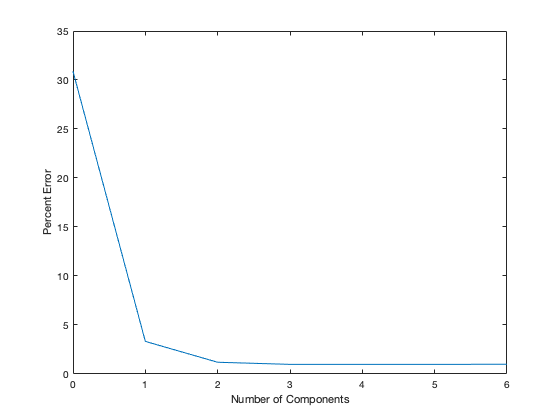

[Xl,Yl,Xs,Ys,beta,pctVar,PLSmsep] = plsregress(X,y,6,"cv",10);
plot(0:6, PLSmsep(2,:))   % row 1 is error in training set
xlabel("Number of Components")
ylabel("Percent Error")

- This plot shows how the error changes with the number of components. 

- It looks like 2 or 3 components is ideal:

[Xl,yl,Xs,Ys,betaPLS,PCTVar] = plsregress(X,y,3);

- Note that PLS adds a column of 1's, so the first value of beta is the intercept.

- Plot the percentage variance explained by each of the 3 components:

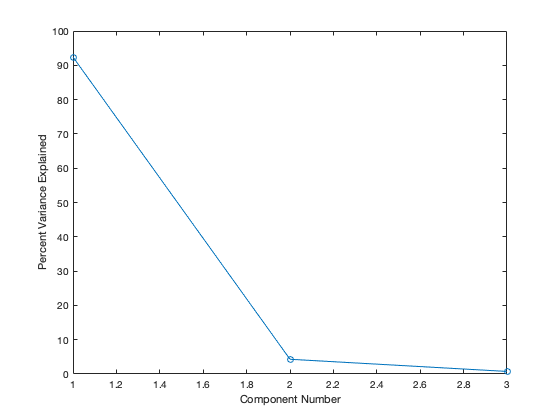

plot(1:3,100*PCTVar(2,:),"-o");
xlabel("Component Number")
ylabel("Percent Variance Explained")

- Compare beta from PLS with other methods.

## Compare Traditional regression vs Lasso, Stepwise, and PLS in Cleveland data

- Predict disease severity using all variables as input.

- For Lasso and PLS, estimate hyperparameters (lambda) in training data with 3-fold cross validation

- Test accuracy of all methods using 5-fold cross validation - output RMSE and correlation in test set

- Find features that are predicted to be most important using each of these methods.

% Load the Cleveland data set
data = readtable("../cleveland_data_revised.xlsx");

Remove rows with NaN and separate data into X and y

data = rmmissing(data);
X = data{:,(1:13)};
y = data.diseaseSeverity;

% Create training and test sets
[trainInd,~,testInd] = dividerand(297,0.7,0,0.3);
Xtrain = X(trainInd)';
Xtest = X(testInd)';
ytrain = y(trainInd);
ytest = y(testInd);

Traditional regression

b1 = regress(ytrain,Xtrain);

%Lasso
[b2, Fit] = lasso(Xtrain,ytrain,"CV",3);

Stepwise

b3 = stepwisefit(Xtrain,ytrain);

Initial columns included: none
Step 1, added column 1, p=0.00277733
Final columns included:  1 
    'Coeff'     'Std.Err.'    'Status'    'P'     
    [0.0277]    [  0.0092]    'In'        [0.0028]



PLS

%[Xl,Yl,Xs,Ys,beta,pctVar,PLSmsep] = plsregress(Xtrain,ytrain,6,"cv",10);
% plot(0:6, PLSmsep(2,:))   % row 1 is error in training set
% xlabel("Number of Components")

Error using plsregress (line 148)
NCOMP must be less than or equal to 1 for these data.

% ylabel("Percent Error")
% [Xl,yl,Xs,Ys,betaPLS,PCTVar] = plsregress(Xtrain,ytrain,1);

indices = crossvalind('kfold',size(data,1),5); RMSE = zeros(5,1); corr = zeros(5,1);

for i = 1:5; test = indices == i; train = ~test;

mean(RMSE) mean(corr)